# Actividad #Test

#### Fecha:

fecha = datetime('now', 'Format', 'dd-MM-yyyy');
disp(['Fecha actualizada: ', char(fecha)])

Fecha actualizada: 05-07-2024


#### Objetivos:

- Leer datos desde el repositorio: Open Energy Data Initiative

- [https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/](https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/)

- Graficar datos

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- [https://es.mathworks.com/help/matlab/ref/ls.htm](https://es.mathworks.com/help/matlab/ref/ls.htm)

- [https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558](https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558)

## Paso 0: Descartar cualquier cambio realizado en el repositorio clonado

%Version Online, Opcion 1:
% Source Control -> Discard all changes
% Source Control -> git pull

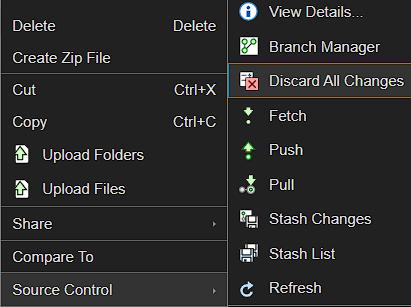

%Version Online, Opcion 2:
% repo = gitrepo;
% discardChanges(repo,repo.ModifiedFiles);
% Source Control -> git pull

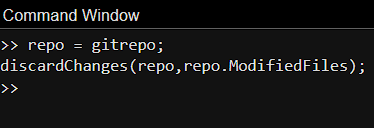

% Version para PC, en el Bash del Git:
% git status
% git reset --hard
% Git pull

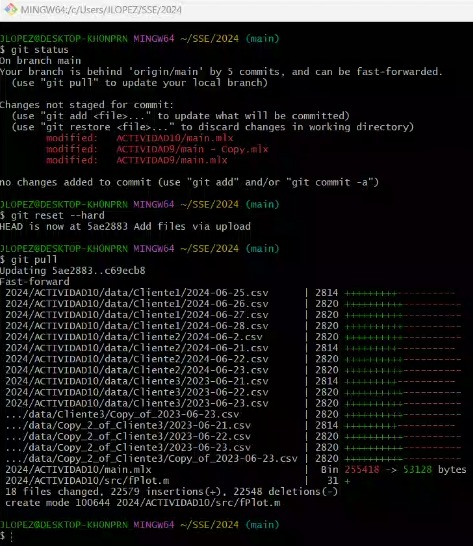

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- Buscar los nombres y **Cargar los datos **de todos los archivos dentro de la carpeta ./data**

%Leer un archivo csv y lo carga como una tabla
filename = FindCSV(datapath);
% Dataset es una tabla donde cada columna es una variable con su 
% respectivo nombre
Dataset=fLoadCellCSV(filename,datapath)

Dataset = 8760×11 table
       Date_Time        Electricity_Facility_kW__Hourly_    Fans_Electricity_kW__Hourly_    Cooling_Electricity_kW__Hourly_    Heating_Electricity_kW__Hourly_    InteriorLights_Electricity_kW__Hourly_    InteriorEquipment_Electricity_kW__Hourly_    Gas_Facility_kW__Hourly_    Heating_Gas_kW__Hourly_    InteriorEquipment_Gas_kW__Hourly_    WaterHeater_WaterSystems_Gas_kW__Hourly_
    ________________    ________________________________    ____________________________    _______________________________    _______________________________    ______________________________________    _________________________________________    ________________________

## **Paso 5- Extraer nombres de variables y crear datetime**

% Extraer todos los nombres de variables de la tabla
% Se hace el cast de cell a string
varnames=string(Dataset.Properties.VariableNames);

% Crear datatime con una frecuencia de muestreo de un dato por hora segun el
% dataset
%Time = Start Time: Step Time: End Time
time = datetime(2004, 1, 1):hours(1):datetime(2004, 12, 31);
% Se elimina el primer valor
time=time(1,2:end)';

% para agregar una nueva variables en la tabla
%Dataset.('Time_Stamp')=time;

## **Paso 6- Graficar todas las variables**

figure;
% Dataset
Variable1=Dataset.(varnames(2));
plot(time,Variable1)
hold on
Variable2=Dataset.(varnames(3));
plot(time,Variable2)
Variable3=Dataset.(varnames(4));
plot(time,Variable3)
Variable4=Dataset.(varnames(5));
plot(time,Variable4)

legend(varnames(2:end));

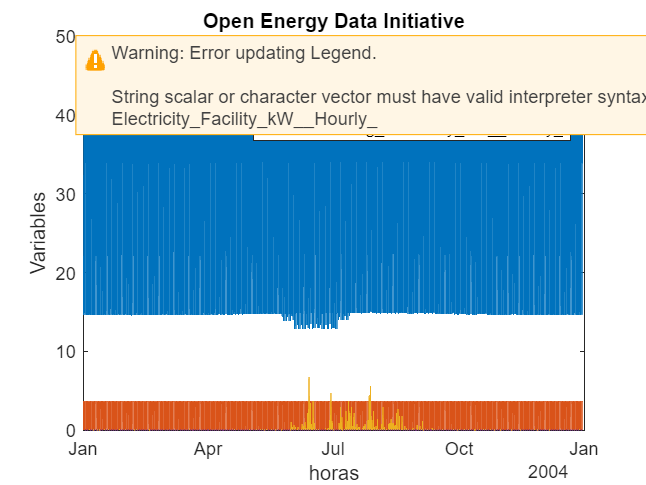

title('Open Energy Data Initiative');
xlabel('horas')
ylabel('Variables')